# Four-Wheel Steering

Copyright 2018 The MathWorks, Inc.

## Kinematic Model

This vehicle has four wheels which can all be driven and steered independently. For simplicity, we assume Ackermann steering such that the vehicle can be approximated as a two-wheel system (commonly known as a bicycle model).

Reference: [https://www.ntu.edu.sg/home/edwwang/confpapers/wdwicar01.pdf](https://www.ntu.edu.sg/home/edwwang/confpapers/wdwicar01.pdf)

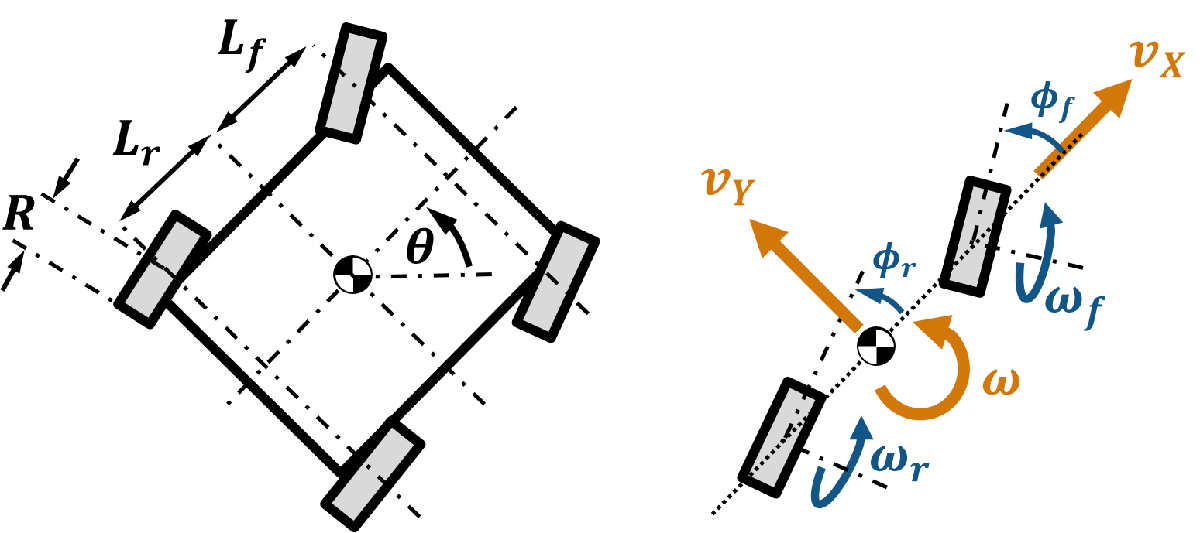

**Inputs:**

- Front and rear wheel speeds $\left\lbrack \omega_f \text{ };\text{ }\omega_r \right\rbrack$, in rad/s

- Front and rear steer angles $\left\lbrack \phi_f ;\phi_r \right\rbrack$, in rad

**Outputs**

- Linear velocities$v_X$ and $v_Y$, in m/s

- Angular velocity $\omega$, in rad/s

**Forward Kinematics**


$$\begin{array}{l}
v_X =\frac{R}{2}{\left(\omega_f \text{ }\cos \phi_f +\omega_{r\text{ }} \cos \phi_r \right)} \\
v_Y =\frac{R}{2}{\left(\omega_f \text{ }\sin \phi_f +\omega_r \text{ }\sin \phi_r \right)}  \\
\omega =\frac{R}{L_f +L_r } \left(\omega_f \text{ }\mathrm{sin}\phi_f -\omega_r \text{ }\sin \phi_r \right) 
\end{array}$$
 

**Inverse Kinematics**

Due to the coupled kinematics of the system, the MATLAB and Simulink files in this toolbox provide 3 different inverse kinematics models.

FRONT STEERING

- Assumption: Rear wheel is not steered

- Inputs: Forward velocity $v_X$ and angular velocity $\omega$


$$\begin{array}{l}
\omega_f =\frac{v_X }{R\text{ }\mathrm{cos}\phi_{f\text{ }} } ,                    {\text{ }\text{ }\text{ }\text{ }\omega }_r =\frac{v_X }{R}\\
\phi_f =\text{atan}{\left(\frac{\omega {\left(L_f +L_r \right)}}{v_X }\right)} ,   {   \phi }_r =0
\end{array}$$


ZERO SIDESLIP

- Assumption: Front and rear wheels steered with opposite angles to minimize sideslip (lateral velocity in Y-direction)

- Inputs: Forward velocity $v_X$ and angular velocity $\omega$


$$\begin{array}{l}
\omega =\frac{v_X }{R\text{ }\mathrm{cos}\phi \text{ }} ,                      \text{   }\omega_r =\omega_f =\omega \\
\phi =\text{atan}{\left(\frac{\omega {\left(L_f +L_r \right)}}{v_X }\right)} ,   {   \phi }_r ={-\phi }_f =\phi 
\end{array}$$


PARALLEL STEERING

- Assumption: Front and rear wheels steered with equal angles, so the vehicle moves without rotating

- Inputs: Linear velocities $v_X$ and $v_Y$


$$\begin{array}{l}
v=\frac{\mathrm{s}\mathrm{i}\mathrm{g}\mathrm{n}{\left(v_x \right)}}{R}\sqrt{v_X^2 +v_Y^2 } ,       {  \omega }_r =\omega_f =\omega \\
\phi =\text{atan}{\left(v_Y /v_X \right)} ,   {              \text{ }\phi }_r ={-\phi }_f =\phi 
\end{array}$$


## MATLAB Usage

Create a `FourWheelSteering` object

wheelRadius = 0.1;          % Wheel radius [m]
wheelDists = [0.3, 0.25];   % Front and rear wheel distances to CG [m]
vehicle = FourWheelSteering(wheelRadius,wheelDists)

vehicle =   FourWheelSteering with properties:

       wheelRadius: 0.1000
    frontWheelDist: 0.3000
     rearWheelDist: 0.2500

Solve forward kinematics

wheelSpd = [1; 1]; 	% Wheel speeds [wf; wr]
steerAng = [pi/8; 0]; 	% Steer angles [phif; phir]	
vel = forwardKinematics(vehicle,wheelSpd,steerAng)

vel =     0.0962
    0.0191
    0.0696

Solve front steering inverse kinematics

vx = 0.5;   % Forward speed [m/s]
w = 1; 	    % Angular velocity [rad/s]
[wheelSpdFS,steerAngFS] = inverseKinematicsFrontSteer(vehicle,vx,w)

wheelSpdFS =     7.4330
    5.0000

steerAngFS =     0.8330
         0

Solve zero sideslip inverse kinematics

vx = 0.5;   % Forward speed [m/s]
w = 1; 	    % Angular velocity [rad/s]
[wheelSpdZS,steerAngZS] = inverseKinematicsZeroSideslip(vehicle,vx,w)

wheelSpdZS =     7.4330
    7.4330

steerAngZS =     0.8330
   -0.8330

Solve parallel steering inverse kinematics

vx = 1; 	% Forward speed [m/s]
vy = 0.3;	% Lateral speed [m/s]
[wheelSpdPS,steerAngPS] = inverseKinematicsParallelSteer(vehicle,vx,vy)

wheelSpdPS =    10.4403
   10.4403

steerAngPS =     0.2915
    0.2915

Reference examples:

- [Discrete-time kinematic simulation](matlab:edit mrsFourWheelSteerDiscrete)

- [Continuous-time kinematic simulation](matlab:edit mrsFourWheelSteerContinuous)

## Simulink Usage

Simulink blocks are in the **Kinematic Models > Four-Wheel Steering** section of the [block library](matlab:mobileRoboticsLib).

Use the **Four-Wheel Steering Forward Kinematics** and **Four-Wheel Steering Inverse Kinematics** blocks to convert between body velocities and wheel velocities and steer angles.

Use the **Four-Wheel Steering Simulation** block to simulate the pose given wheel speeds as inputs. You can configure the initial pose and simulation sample time.

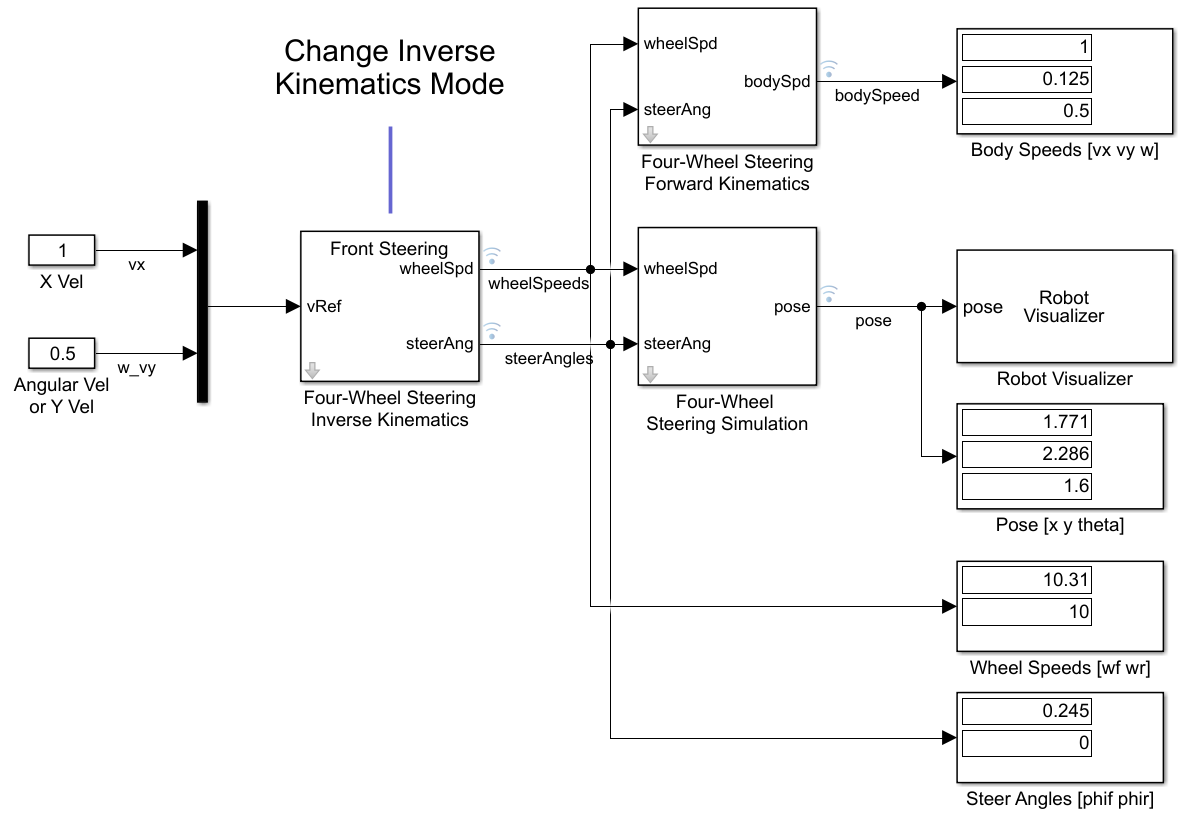

Reference example:

- [Four-wheel steering kinematic simulation](matlab:mrsFourWheelSteerModel)